## Загрузка файлов

close all;
clear variables;

airRaw = fscanf(fopen('data\air.txt', 'r'), '%f', [2 Inf]);
breathRaw = fscanf(fopen('data\breath.txt', 'r'), '%f', [2 Inf]);
tt = fscanf(fopen('data\totalTime.txt', 'r'), '%f');
temperature = fscanf(fopen('data\temperature.txt', 'r'), '%f');
sampFreq = fscanf(fopen('data\samplingFrequency.txt', 'r'), '%f');
waterFraction = fscanf(fopen('data\volumeFractionWater.txt', 'r'), '%f');
fclose('all');

ttRaw = (0:(1 / sampFreq):tt)';

distance = 1.158;

## Нормировка

windowSize = 5;
b = (1 / windowSize) * ones(1, windowSize);
a = 1;
airFiltered_1 = filter(b, a, airRaw(1, :));
airFiltered_2 = filter(b, a, airRaw(2, :));
breathFiltered_1 = filter(b, a, breathRaw(1, :));
breathFiltered_2 = filter(b, a, breathRaw(2, :));

start = 30;

airFiltered_1 = airFiltered_1(:, start:end);
airFiltered_2 = airFiltered_2(:, start:end);
breathFiltered_1 = breathFiltered_1(:, start:end);
breathFiltered_2 = breathFiltered_2(:, start:end);
tt = ttRaw(start:end)';

cAir_1 = polyfit(tt, airFiltered_1, 3);
cBreath_1 = polyfit(tt, breathFiltered_1, 3);
cAir_2 = polyfit(tt, airFiltered_2, 3);
cBreath_2 = polyfit(tt, breathFiltered_2, 3);

air_1 = airFiltered_1 - polyval(cAir_1, tt);
airNorm_1 = air_1 ./ max(air_1);

air_2 = airFiltered_2 - polyval(cAir_2, tt);
airNorm_2 = air_2 ./ max(air_2);

breath_1 = breathFiltered_1 - polyval(cBreath_1, tt);
breathNorm_1 = breath_1 ./ max(breath_1);

breath_2 = breathFiltered_2 - polyval(cBreath_2, tt);
breathNorm_2 = breath_2 ./ max(breath_2);

## Построение графиков для определения скорости

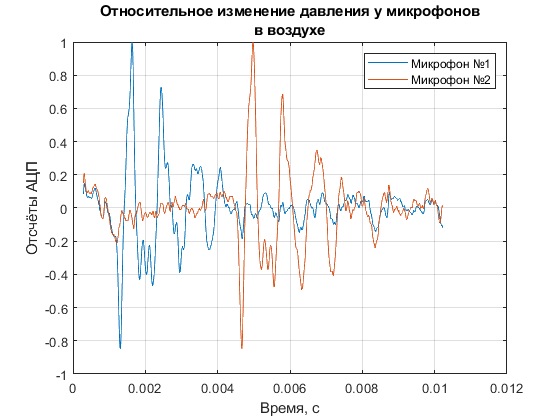

figure_1 = figure();

plot(tt, airNorm_1)
hold on;
plot(tt, airNorm_2)
hold off;

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2');

saveas(figure_1, "air.png")

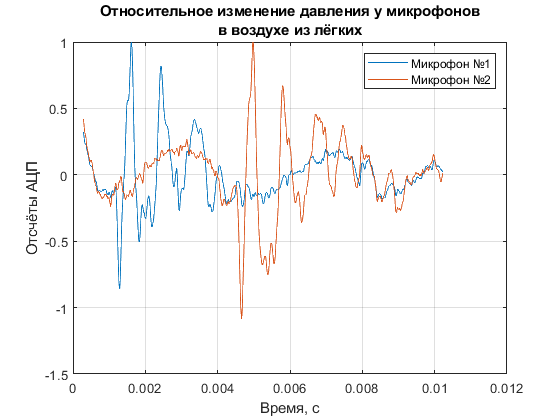

figure_2 = figure();

plot(tt, breathNorm_1)
hold on;
plot(tt, breathNorm_2)
hold off;

grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из лёгких'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2')

saveas(figure_2, "breath.png")

## Определение скорости звука

В обычном воздухе:

tAir_1 = tt(airNorm_1 == 1);
tAir_2 = tt(airNorm_2 == 1);
diff_air = tAir_2 - tAir_1;

V_air = distance / diff_air

V_air = 345.6716

В выдыхаемом воздухе:

tBreath_1 = tt(breathNorm_1 == 1);
tBreath_2 = tt(breathNorm_2 == 1);
diff_breath = tBreath_2 - tBreath_1;

V_breath = distance / diff_breath

V_breath = 344.6429

## Вывод зависимости скорости звука 

от содержания в воздухе CO2. 

Для начала объявим переменные:

R = 8.314;

mAir = 28.97;
mH2O = 18.01;
mCO2 = 44.01;

CpAir = 1.0036;
CpH2O = 1.863;
CpCO2 = 0.838;

CvAir = 0.7166;
CvH2O = 1.403;
CvCO2 = 0.649;

CO2fraction = 0:0.00001:0.02;
our_vitesse = V_breath * ones(1, length(CO2fraction));

Рассчитаем реобходимые параметры:

mu = (1 - waterFraction - CO2fraction)*mAir + waterFraction * mH2O + CO2fraction * mCO2;

Cp = CpAir*(1 - waterFraction - CO2fraction)*mAir + CpH2O*waterFraction * mH2O + CpCO2*CO2fraction * mCO2;
Cv = CvAir*(1 - waterFraction - CO2fraction)*mAir + CvH2O*waterFraction * mH2O + CvCO2*CO2fraction * mCO2;
gamma = Cp ./ Cv;

Теперь построим график зависимости скорости звука от концентрации:

vitesse = sqrt(1000 * gamma * R * (temperature + 273.15) ./ mu);
concentration = CO2fraction(vitesse <= V_breath);
concentration = concentration(1)

concentration = 0.0092

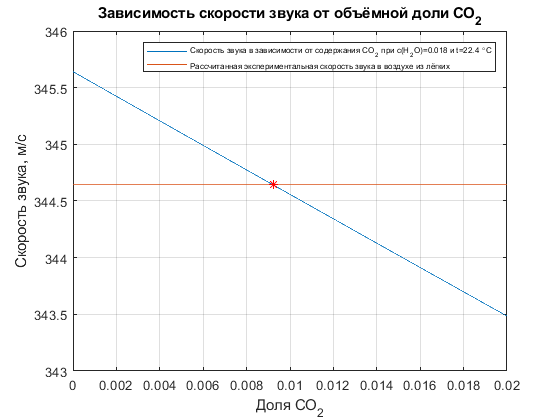


figure_3 = figure();
plot(CO2fraction, vitesse)
hold on;8
plot(CO2fraction, our_vitesse)
plot(concentration, V_breath, 'r*')
hold off;

grid on;
title('Зависимость скорости звука от объёмной доли CO_2');
ylabel('Скорость звука, м/с');
xlabel('Доля CO_2');
legend(['Скорость звука в зависимости от содержания CO_2 при c(H_2O)=', num2str(waterFraction),' и t=', num2str(temperature), ' \circC'], 'Рассчитанная экспериментальная скорость звука в воздухе из лёгких', 'fontSize', 6)

saveas(figure_3, "result.png")